# **PRACTICE 5 - OPTIMIZATION TECHNIQUES**

**Andrés Herencia y Antonio Fernández**

**MUTECI 2023-2024**

## **Exercise 1**

Using the data from the file `datos_regr_orto.txt,` the following is requested: 

    a) Propose an optimization model to solve the orthogonal regression problem for the model $y=\beta_0 +\beta_1 x+\beta_2 x^2$.

    b) Solve it using the appropriate software.

    c) Compare the result with the standard regression model (a graphical comparison is acceptable).

### Solution

#### a) Propose an optimization model to solve the orthogonal regression problem for the model $y=\beta_0 +\beta_1 x+\beta_2 x^2$.

a) First of all, we will read our data:

clear
cd('C:\Users\andre\Documents\UNIVERSIDAD\MUTECI\BLOQUE 2\TOPT\lab\P5\')
clc

fid = fopen('datos_regr_orto.txt', 'r');
fgetl(fid);
data = textscan(fid, '%f %f');
fclose(fid);
x = data{1}; x2 = x.^2;n = length(x);
X = [ones(n,1),x,x2];
y = data{2};
data = [y,x]

data =     4.8000    0.2000
    7.1000    0.9000
    5.3000    2.2000
    1.8000    2.9000
   -2.8000    4.1000
  -10.5000    5.2000


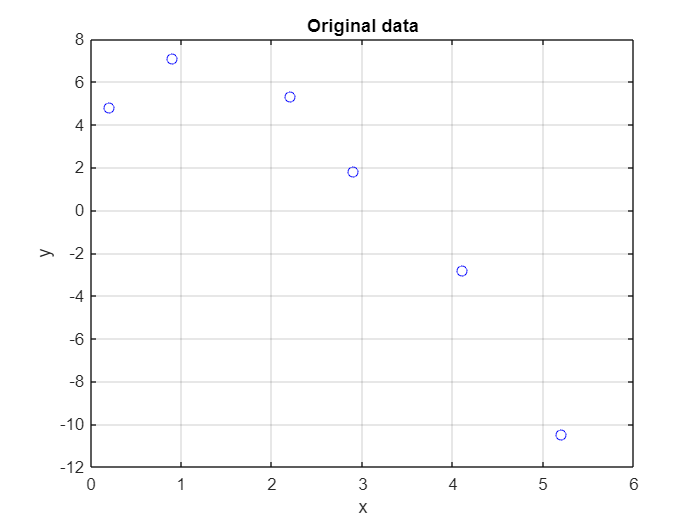

clc
figure(1)
plot(x,y,'bo')
xlabel('x')
ylabel('y')
title('Original data')
grid on

We define $\epsilon_i ={Y_i }^* -Y_i$ as the error associated to $Y_i$, and $\delta_i ={X_i }^* -X_i$ as the associated error to each $X_i$, with $i=1,\ldots,n\ldotp$

Then, we consider the orthogonal problem to solve an orthogonal regression problem as it follows.


$$\min_{\beta, \epsilon_i, \delta_i} \quad \sum_{i=1}^{n} ( \epsilon_i^{2} + \delta_i^{2} ) \\
\textrm{such to} \quad Y_i = f(X_i + \delta_i; \beta) - \epsilon_{i}, \quad i=1,\dots,n.
$$


If we reordenate the problem substituting $\epsilon_{i\;}$and $\delta_i$ in function of $X_i$ and $Y_i$, we finally obtain:


$$\min_{\beta^*, \delta^*} \sum_{i=1}^{n} \{ (f(X_i + \delta_i; \beta) - Y_i)^2 + \delta_i^{2}\}$$


And if we substitute for our concrete problem we get:


$$\min_{\beta^*, \delta^*} \sum_{i=1}^{n} \{ [ \beta_0 + \beta_1 x^* + \beta_2 x^{*2} - Y_i]^2 + (x^*-x)^2 + (x^{*2} - x^2)^2\}$$


Where the $*$ symbol represents our estimation.

#### b) Solve it using the appropriate software.

The initial values of the errors associated with $x$ will be the $y$ vector, meanwhile, the $\beta$ coefficients could be the result of making the quadratic regression (this regression can be perform via the `polyval` command). Then:

b2 = polyfit(x,y,2);
O = [b2,x']

O =    -0.9683    2.0096    5.1102    0.2000    0.9000    2.2000    2.9000    4.1000    5.2000


orto = @(E) orthogonal_regression(x,y,E);
[error, fval] = fminunc(orto,O)


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


error =     5.1103    2.0095   -0.9682    0.2000    0.9000    2.2000    2.9000    4.1000    5.2001


fval = 2.6135

beta = error(1:3);
eps = error(4:end);

Finally our orthogonal regression model over $y=\beta_0 +\beta_1 x+\beta_2 x^2$ with 


$$\begin{cases}
\beta_0 = 5.1103 \\
\beta_1 =  2.0095 \\
\beta_2 =  -0.9682
\end{cases}$$


xq = min(x):length(x)/100:max(x);
y_orto = beta(1) + beta(2).*xq + beta(3).*xq.^2;

#### c) Compare the result with the standard regression model (a graphical comparison is acceptable).

X = [ones(length(x),1),x];
b1 = regress(y,X);
Y1 = b1(1) + b1(2).*x;
spl = spline(x,y,xq)

spl =     4.8000    5.0884    5.3596    5.6137    5.8506    6.0704    6.2730    6.4586    6.6272    6.7788    6.9134    7.0310    7.1317    7.2155    7.2824    7.3325    7.3658    7.3823    7.3820    7.3650    7.3314    7.2810    7.2140    7.1304    7.0301    6.9134    6.7801    6.6303    6.4640    6.2812    6.0821    5.8665    5.6346    5.3864    5.1219    4.8429    4.5517    4.2510    3.9431    3.6307    3.3161    3.0020    2.6908    2.3851    2.0873    1.8000    1.5250    1.2619    1.0093    0.7662


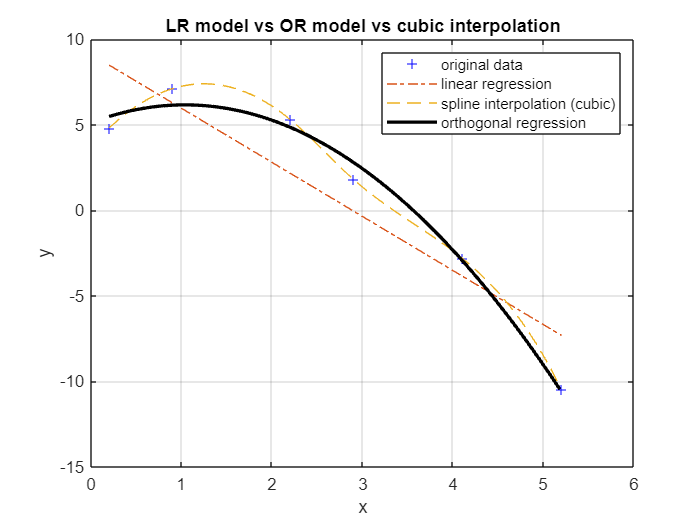

clc
figure(2)
plot(x,y,'b+',x,Y1,'-.')
hold on
plot(xq,spl,'--',"MarkerFaceColor","#77AC30")
hold on
plot(xq,y_orto,'k-','lineWidth',2)
title('LR model vs OR model vs cubic interpolation')
grid on
xlabel('x')
ylabel('y')
legend('original data', 'linear regression', 'spline interpolation (cubic)', 'orthogonal regression')

Indeed, data fits so much better compared with the linear regression. Additionally, we have compared these values with a spline interpolation (i.e., the cubic interpolation of our points), and we can affirm that the error is acceptable.

## Exercise 2

Using the data from the file `svm_complejo.txt` the following is requested: 

    a) Represent the data to try to identify a suitable kernel function. 

    b) With the available software (no need to program it), attempt to test different kernel functions to solve the classification problem.

### Solution

#### a) Represent the data to try to identify a suitable kernel function. 

clear; clc
data = readtable('svm_complejo.csv','Delimiter',';');
x1 = data.x1; x2 = data.x2; y = data.y; X = [x1,x2];
data

data = 28×3 table
    x1     x2     y 
    ___    ___    __

      2    115     1
    3.5    105     1
      4    130     1
    4.5    125     1
      5    125     1
      6    110     1
    7.5    109     1
      8    105     1
    7.6    130     1
    7.8    130     1
    8.1    180     1
    8.3    190     1
    8.1    180     1
    2.5    130    -1
      3    145    -1
      4    150    -1


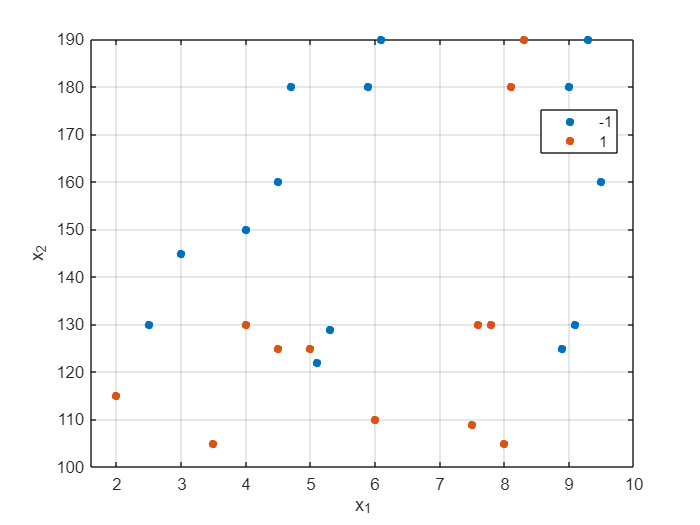

clf
figure(1)
gscatter(x1,x2,y)
grid on
xlabel('x_1')
ylabel('x_2')

Graphically, we can see that it does not exist a linear discriminant. It also seems that data can not be fitted easily to a polynomial curve. As for using a sigmoid-based kernel, it would be a good approximation although it would present some underfitting. 

So, since in general the groups are not too mixed with each other and there seems to be a certain distance between the different classes, we think that the best option will be to use a **Gaussian kernel** (although we cannot guarantee a priori that it fits perfectly or that tend to overfitting).

In any case, we are going to do an analysis based on all the kernel types and we will comment on them later.

#### b) With the available software (no need to program it), attempt to test different kernel functions to solve the classification problem.

As a first approach, we will try with the linear kernel. Then:

- **Linear Kernel**

model2 = fitcsvm(X, y, "KernelFunction", "linear");

Our discriminant is given by the beta coefficients

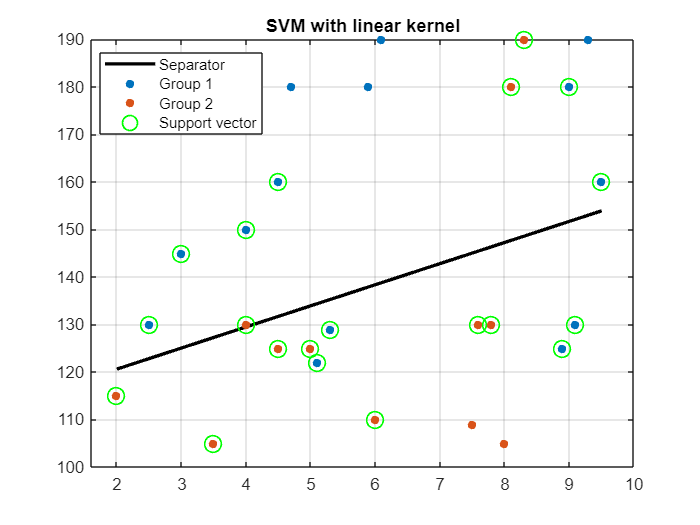

w = model2.Beta;
b = model2.Bias;
kx1 = min(X(:,1)):0.1:max(X(:,1));
kx2 = (-w(1) * kx1 - b)/w(2); 

clf
figure(2)
plot(kx1, kx2, 'k', 'LineWidth', 2);
hold on;
h(1:2) = gscatter(X(:,1),X(:,2),y);
h(3) = plot(X(model2.IsSupportVector,1),...
    X(model2.IsSupportVector,2),'go','MarkerSize',10, 'LineWidth',1);
title('SVM with linear kernel')
grid on
legend('Separator', 'Group 1', 'Group 2','Support vector','Location','Best')
hold off;

**Results**: 2 points in group 1 misclassified; 5 points in group 2 misclassified. This is, indeed, a very bad result, specially for the second class.

- **Polynomial Kernel**

We will try with the simpler firstly, degree 2

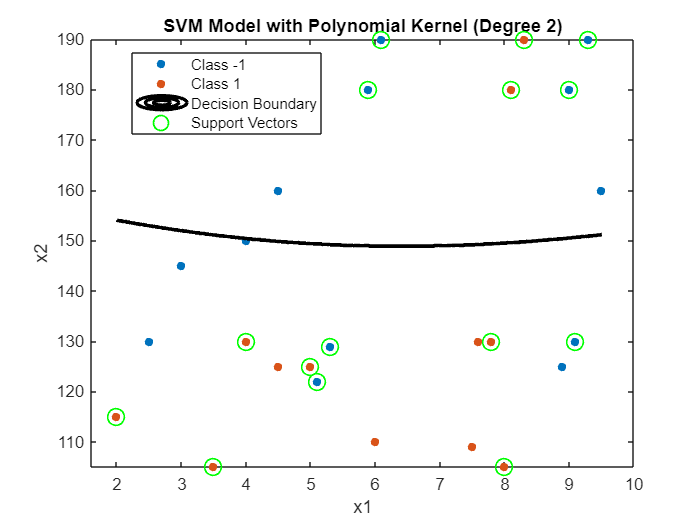

model2 = fitcsvm(X, y, 'KernelFunction', 'polynomial', 'PolynomialOrder', 2);
sv = model2.SupportVectors;
% Grid
[xGrid, yGrid] = meshgrid(linspace(min(X(:, 1)), max(X(:, 1)), 1000), ...
                          linspace(min(X(:, 2)), max(X(:, 2)), 1000));
gridPoints = [xGrid(:), yGrid(:)];
predLabels = predict(model2, gridPoints);
figure;
gscatter(X(:, 1), X(:, 2), y);
hold on
contour(xGrid,yGrid,reshape(predLabels, size(xGrid)), 'k', 'LineWidth', 2);
plot(sv(:, 1), sv(:, 2), 'go', 'MarkerSize', 10, 'LineWidth', 1);
title('SVM Model with Polynomial Kernel (Degree 2)');
xlabel('x1');
ylabel('x2');
legend('Class -1', 'Class 1', 'Separator', 'Support Vectors');
hold off;

As we can see, **this method does not fit our data at all**. If we try to use another polynomial kernel with higher degree, we cannot perform it.

- **Gaussian kernel**

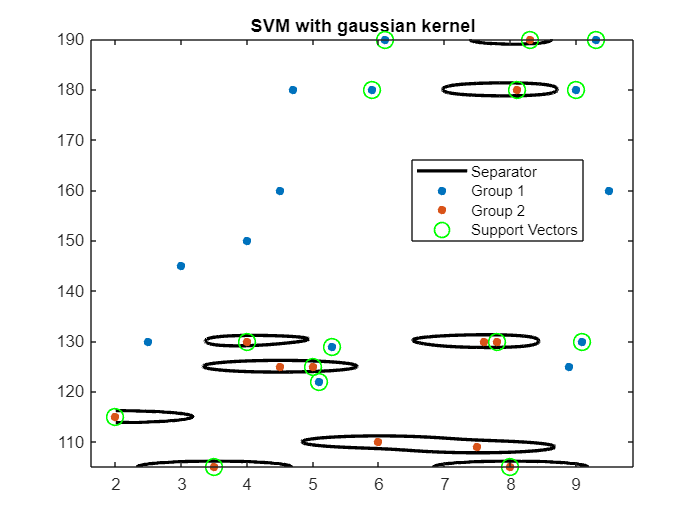

model3 = fitcsvm(X, y, "KernelFunction","rbf"); % rbf states for radial basis function
[x1Grid, x2Grid] = meshgrid(linspace(min(X(:, 1)), max(X(:, 1)), 1000), ...
                          linspace(min(X(:, 2)), max(X(:, 2)), 1000));
xGrid = [x1Grid(:),x2Grid(:)];
[~,scores1] = predict(model3,xGrid); % The scores

figure(3)
contour(x1Grid,x2Grid,reshape(scores1(:,2),size(x1Grid)),[0 0],'k','LineWidth',2);
hold on
gscatter(X(:,1),X(:,2),y);
plot(X(model2.IsSupportVector,1),...
    X(model2.IsSupportVector,2),'go','MarkerSize', 10, 'LineWidth', 1);
title('SVM with gaussian kernel')
legend({'Separator','Group 1','Group 2','Support Vectors'},'Location','Best');
hold off

This method fits with our data, but it seems like the algorithm has generated a higher number of ellipsoids than expected. Furthermore, ellipsoids have a very small area. In other words, the SVM algorithm has overfitted (a problem that is named *curse of the dimensionality*).

A way to solve this is applying cross-validation (but it is not object of this practice). Then, a model can be selected depending on information criterion such as BIC or AIC values (but again, this is not the objective of this practice). The code for the cross validation is on annexes.

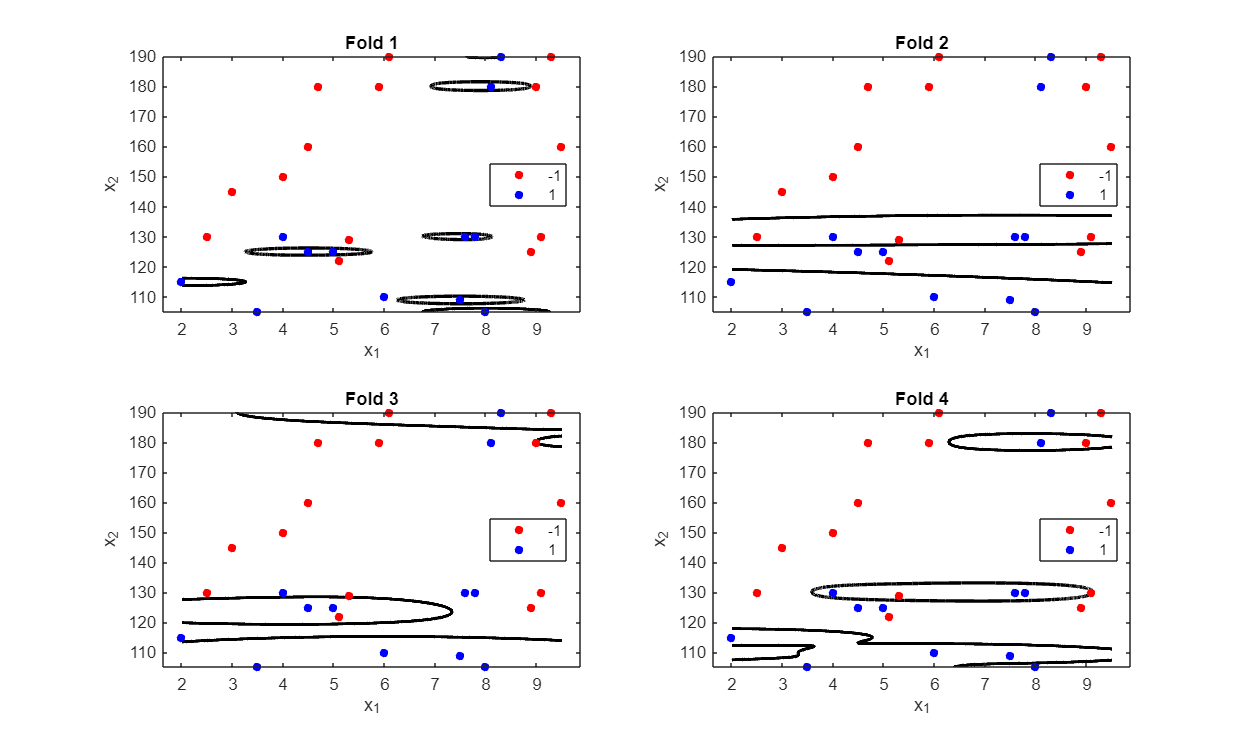

cross_val_svm(y,X,4,'rbf') % this is a function created by me which makes the cross-validation process on n-folds.

**Conclusion: the model which best suits for this use case is the Gaussian-kernel-based model.**

## **Annexes**

### **Cross Validation for SVM function**

function [] = cross_val_svm(y,X,n,svm_method)
%% Cross-validation of a svm model.

% Create a cross-validation partition
cvp = cvpartition(y, 'KFold', n); % 5-fold cross-validation

% Initialize an array to store the trained SVM models
models = cell(cvp.NumTestSets, 1);

% Create a new figure and specify its size
fig = figure('Position', [100, 100, 1000, 600]);

for i = 1:cvp.NumTestSets
    % Split the data into training and testing sets
    trainIdx = cvp.training(i);
    testIdx = cvp.test(i);
    X_train = X(trainIdx, :);
    y_train = y(trainIdx);
    X_test = X(testIdx, :);
    y_test = y(testIdx);

    % Train the SVM model with an RBF kernel
    SVMModel = fitcsvm(X_train, y_train, 'KernelFunction', svm_method, 'BoxConstraint', 1, 'KernelScale', 'auto');

    % Store the trained model
    models{i} = SVMModel;
    
    if mod(n,2)==1
        m = floor(n/2) + 1;
    else
        m = n/2;
    end
       
    % Create subplots with larger size
    subplot(2, m, i, 'Parent', fig); % Adjust the subplot arrangement as needed

    % Create a grid for plotting
    x1 = linspace(min(X(:, 1)), max(X(:, 1)), 3000);
    x2 = linspace(min(X(:, 2)), max(X(:, 2)), 3000);
    [X1, X2] = meshgrid(x1, x2);
    XGrid = [X1(:), X2(:)];

    % Calculate scores for the grid points
    scores = predict(SVMModel, XGrid);
    scores = reshape(scores, size(X1));

    % Plot the decision boundary
    contour(x1, x2, scores, [0, 0], 'k', 'LineWidth', 2);
    hold on;

    % Plot the data points
    gscatter(X(:, 1), X(:, 2), y, 'rb');
    
    title(['Fold ', num2str(i)]);
    xlabel('x_1');
    ylabel('x_2');
end
end